# Exercici 3 -Parcial

#### Apartat a)

clear all
close all
format long

f = @(x)  x.*exp(-x.^2)        % the function to interpolate

f = function_handle with value:
    @(x)x.*exp(-x.^2)


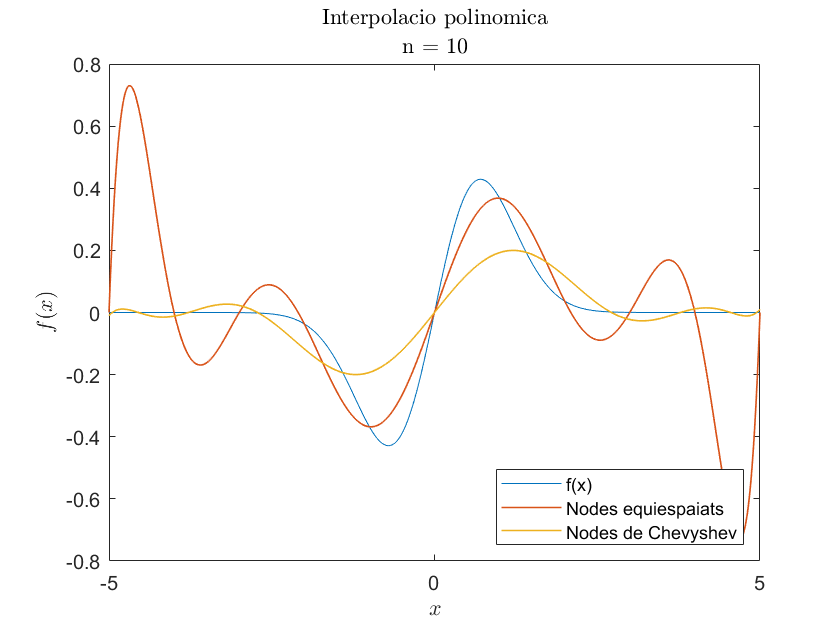

% interpolacio

n = 10;                % the degree of the interpoland
% Create n nodes
jj = 0:n;
xj = -5+10*jj/n;         %equispaced
xj_chev = 5*cos((2*jj+1)*pi/(2*n+2));    %Chebyshev
 
% Solve the system to find the a_i coefficients of the polynomial interpolation 
fx = f(xj)';
fx_chev = f(xj_chev)';
a_equi_10 = polyfit(xj,fx,n);
a_chev_10 = polyfit(xj_chev,fx_chev,n);

% Malla per a representar els polinomis
mesh = linspace(-5,5,500);

% Plot f(x) vs the polynomical approximation    
figure(1)
plot(mesh, f(mesh))
hold on
plot(mesh, polyval(a_equi_10,mesh), 'Linewidth',0.8)   
plot(mesh, polyval(a_chev_10,mesh), 'Linewidth',0.8)
title('Interpolacio polinomica', 'Interpreter', 'latex')
subtitle('n = 10', 'Interpreter', 'latex')
xlabel('$x$', 'Interpreter', 'latex')
ylabel('$f(x)$', 'Interpreter', 'latex')
legend('f(x)', 'Nodes equiespaiats', 'Nodes de Chevyshev', 'Location','southeast')


% Repetim la interpolació per n = 20
n = 20;                % the degree of the interpoland

% Create n  nodes
jj = 0:n;
xj = -5+10*jj/n;         %equispaced
xj_chev = 5*cos((2*jj+1)*pi/(2*n+2));    %Chebyshev
 
% Solve the system to find the a_i coefficients of the polynomial interpolation 
fx = f(xj)';
fx_chev = f(xj_chev)';
a_equi_20 = polyfit(xj,fx,n);

a_chev_20 = polyfit(xj_chev,fx_chev,n);

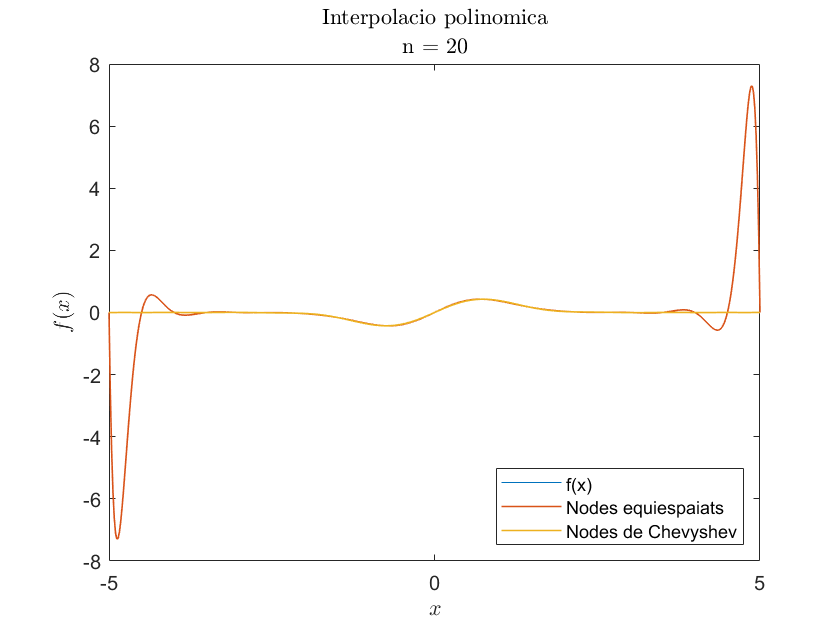


% Malla per a represnetar els polinomis
mesh = linspace(-5,5,500);

% Plot f(x) vs the polynomical approximation    
figure(2)
plot(mesh, f(mesh))
hold on
plot(mesh, polyval(a_equi_20,mesh), 'Linewidth',0.8)   
plot(mesh, polyval(a_chev_20,mesh), 'Linewidth',0.8)
title('Interpolacio polinomica', 'Interpreter', 'latex')
subtitle('n = 20', 'Interpreter', 'latex')
xlabel('$x$', 'Interpreter', 'latex')
ylabel('$f(x)$', 'Interpreter', 'latex')
legend('f(x)', 'Nodes equiespaiats', 'Nodes de Chevyshev', 'Location','southeast')


% En aquest cas, per a nodes equiespaiats, la polinomi esta mal condicionat

#### Apartat b)

nodes = (-4.75 + [0:19]/2)';    % nodes on mesurar l'error

[error_equi_10, acumulat1] = error_polinomi(a_equi_10, nodes);
[error_equi_20, acumulat2] = error_polinomi(a_equi_20, nodes);
[error_chev_10, acumulat3] = error_polinomi(a_chev_10, nodes);
[error_chev_20, acumulat4] = error_polinomi(a_chev_20, nodes);

% Taula amb els errors parcials
taula = [error_equi_10, error_equi_20, error_chev_10, error_chev_20];
T = array2table(taula,"VariableNames",{'Equispaced n = 10','Equispaced n = 20','Chevyshev n = 10','Chevyshev n = 20'})

T = 20×4 table
     Equispaced n = 10       Equispaced n = 20        Chevyshev n = 10        Chevyshev n = 20   
    ___________________    _____________________    ____________________    _____________________

      -0.70764244369334           4.989087547282     -0.0106257317066881     -0.00207979597139402
     -0.284819392729106       -0.462046674167661       0.014218070846673      -0.0016736189845368
      0.147188749045529       0.0761510581933611    -0.00183754104522653      0.00294921993115292
     0.0932782172452307      -0.0188049223826293     -0.0266037947102591     -0.00325529731555055
    -0.0708976514068468      0.00639290447784832     -0.0048554906183292      0.00184962426070026
    -0.0635547035837196     -0.00283610527757782      0.0577994636635908      0.00268960701698634
      0.065314360906494       0.0015754990046513      0.07581286


% Taula amb l'error acumulat
taula2 = [acumulat1, acumulat2, acumulat3, acumulat4];
T1 = array2table(taula2,"VariableNames",{'Equispaced n = 10','Equispaced n = 20','Chevyshev n = 10','Chevyshev n = 20'})

T1 = 1×4 table
    Equispaced n = 10    Equispaced n = 20    Chevyshev n = 10      Chevyshev n = 20 
    _________________    _________________    _________________    __________________

    1.13656919459218     7.08670417552298     0.471728733860395    0.0283912318887995


function [error, err_acumulat] = error_polinomi(coeffs, nodes)
    f = @(x)  x.*exp(-x.^2);      % funcio real
    f = f(nodes);
    f_aprox = polyval(coeffs,nodes);
    error = f - f_aprox;
    err_acumulat = norm(error);
end